**Import Data**

tic
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');
% read data from excel S&P500.csv
StockData = readtable('S&P500.csv','ReadVariableNames',true);

**Pre-Proccessing**

%Ensures the data is the correct data type
if isnumeric(StockData.Open) == false
    Open =cellfun(@str2double,StockData.Open);
    High = cellfun(@str2double,StockData.High);
    Low = cellfun(@str2double,StockData.Low);
    Close = cellfun(@str2double,StockData.Close);
    AdjustedClose = cellfun(@str2double,StockData.AdjClose);
    Volume = cellfun(@str2double,StockData.Volume);
else
    Open = StockData.Open;
    High = StockData.High;
    Low = StockData.Low;
    Close = StockData.Close;
    AdjustedClose = StockData.AdjClose;
    Volume =  StockData.Volume;
end
Date = StockData.Date;

%Changes the data from table to timetable
StockData_TimeTable = timetable(Date,Open,High,Low,Close,Volume);
StockData_Close = StockData_TimeTable.Close;
%Checks for missing Data
%Fills the missing data with previous value
if any(any(ismissing(StockData_TimeTable)))==true
    StockData_TimeTable = fillmissing(StockData_TimeTable,'previous');
end

Normallizes the data. 

StockData_TimeTable = normalize(StockData_TimeTable,"zscore");

Data splitting

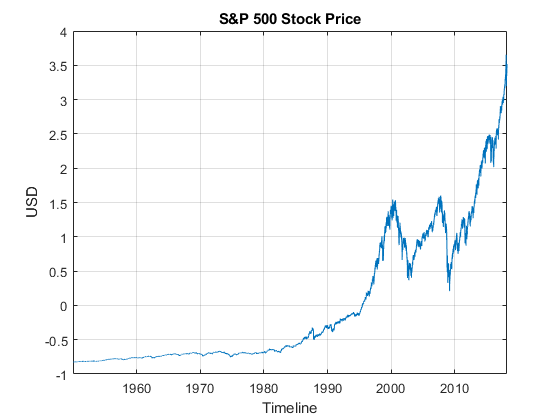

plot(StockData_TimeTable.Date,StockData_TimeTable.Close);
title('S&P 500 Stock Price');
ylabel('USD');
xlabel('Timeline');
grid on

% get Year data out
trainingStart_date = '2010-10-06';
trainingEnd_date = '2010-11-30';
predictionStart_date = '2011-01-01';
predictionEnd_date = '2011-02-28';
% sets the time range for the predication
predictionRange = timerange(predictionStart_date,predictionEnd_date);
Prediction_Close = StockData_TimeTable(StockData_TimeTable.Date(predictionRange),:);
Prediction_Close = timetable2table(Prediction_Close(:,"Close"));
Prediction_Close = Prediction_Close(:,2);
Prediction_Close = table2array(Prediction_Close);


tr = timerange(trainingStart_date, trainingEnd_date);
Training_TimeTable = StockData_TimeTable(StockData_TimeTable.Date(tr),:);
Training_Close = timetable2table(Training_TimeTable(:,"Close"));
Training_Close = Training_Close(:,2);
Training_Close = table2array(Training_Close);
% clear unwanted variables
clear ('Open','Close','Date','AdjustedClose','High','Low','Volume','tr','StockData');

## Exploratory Data Analysis

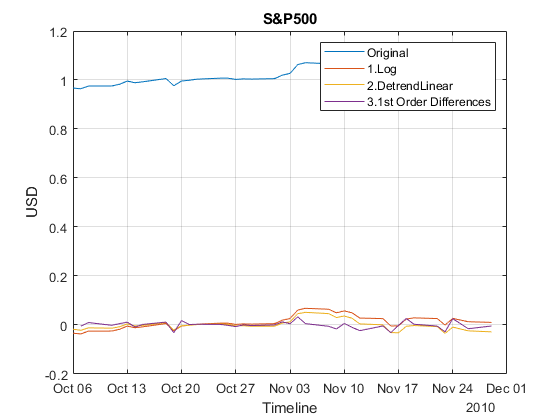

% Transform Data into Stationary Data

% Log
Training_TimeTable.CloseLog = log(Training_TimeTable.Close);

% Remove Linear trend
Training_TimeTable.CloseLogLinear = detrend(Training_TimeTable.CloseLog);

%Perform Differences
CloseLogLinearDifferences = diff(Training_TimeTable.CloseLogLinear);

%View the data
figure
plot(Training_TimeTable.Date,Training_TimeTable.Close);
hold on
plot(Training_TimeTable.Date,Training_TimeTable.CloseLog);
plot(Training_TimeTable.Date,Training_TimeTable.CloseLogLinear);
plot(Training_TimeTable.Date(2:end),CloseLogLinearDifferences);
title('S&P500');
ylabel('USD');
xlabel('Timeline');
legend('Original','1.Log','2.DetrendLinear','3.1st Order Differences')
grid on
hold off

% Test Stationary
% Hypothesis test : Augmented Dickey-filer, KPSS, Leybourne-McCabe, Philip-Peron, Variance Ratio
% Hypothesis test : Egale's ARCH, Ljung-Box Q-test
[h,~] = adftest(CloseLogLinearDifferences);
% if test is valid, it will return 1 or else 0
% P-Value will also verify the stationarity of data, It may get extremely low if your data is not valid.
display(h)

h = logical
   1


## **Find the best fit model of ARIMA**

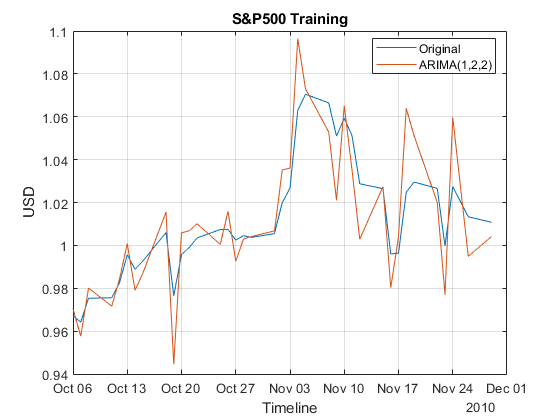

ARIMA_CloseFinal = arima(0,4,4);
[ARIMA_CloseFinal,~,~] = estimate(ARIMA_CloseFinal,Training_TimeTable.Close,'display','off');

residual = infer(ARIMA_CloseFinal,Training_TimeTable.Close);
prediction = Training_TimeTable.Close + residual;

figure
plot(Training_TimeTable.Date,Training_TimeTable.Close);
hold on
plot(Training_TimeTable.Date,prediction);
title('S&P500 Training');
ylabel('USD');
xlabel('Timeline');
legend('Original','ARIMA(1,2,2)','Location','best');
grid on
hold off

## FORECASTING THE DATA

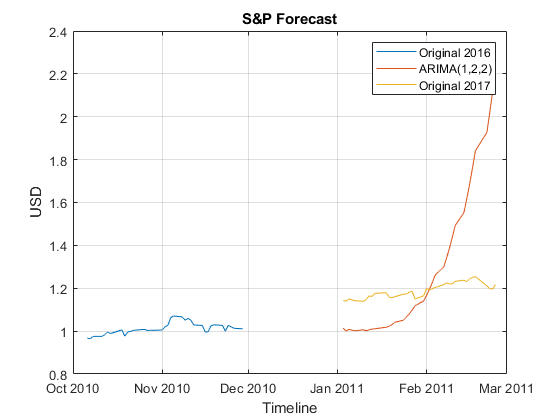

Forecast_TimeTable=StockData_TimeTable(StockData_TimeTable.Date(predictionRange),:);

len=length(Forecast_TimeTable.Close);
ARIMA_CloseFinalForecast = forecast(ARIMA_CloseFinal,len,'Y0',Training_TimeTable.Close);
%plots the forecast
figure
plot(Training_TimeTable.Date,Training_TimeTable.Close);
hold on
% forecast
plot(Forecast_TimeTable.Date,ARIMA_CloseFinalForecast);
plot(Forecast_TimeTable.Date,Forecast_TimeTable.Close);
title('S&P Forecast');
ylabel('USD');
xlabel('Timeline');
legend('Original 2016','ARIMA(1,2,2)','Original 2017');
grid on
hold off

observed = Forecast_TimeTable.Close;
prediction = ARIMA_CloseFinalForecast;
mape = mean(abs((observed - prediction)./observed))*100

mape = 19.9614


toc

Elapsed time is 12.021171 seconds.
